%%<<<<<<<<<<<<<<<<<<< EIS data >>>>>>>>>>>>>>>>>>>>>
Freq_eis = eisdata(:, 1);
Real_bat_eis = eisdata(:, 2);
Imag_bat_eis = eisdata(:, 3);

% Calculate magnitude and phase
MAG_Z_eis = abs(Real_bat_eis + 1i * Imag_bat_eis);
Phase_Z_eis = angle(Real_bat_eis + 1i * Imag_bat_eis) * 180 / pi;

%%<<<<<<<<<<<<<<< simulation data >>>>>>>>>>>>>>>>>>>>
%%<<<<<<<<<<<<<<< 2500 >>>>>>>>>>>>>>
%setup for FFT
L_sim2500=round(T_sim_2500/Ts_2500)+1;
Fs_2500=1/Ts_2500;
f_b_2500=f_clk_2500/L_MLBS;

%FFT for cell voltage & current
FFT_v_sim2500 = fft(out_2500.V_bat.Data, L_sim2500);
FFT_i_sim2500 = fft(-out_2500.I_bat.Data, L_sim2500);

% Initialize arrays to store results
Freq_sim2500 = zeros(1, 25);
MAG_Z_sim2500 = zeros(1, 25);
Phase_Z_sim2500 = zeros(1, 25);
Real_bat_sim2500 = zeros(1, 25);
Imag_bat_sim2500 = zeros(1, 25);

% Loop 
k_values_sim2500 = 1:25;
for idx = 1:length(k_values_sim2500)
    k_sim2500 = k_values_sim2500(idx);
    N_k_sim2500 = round(f_b_2500 * k_sim2500 * L_sim2500 / Fs_2500 + 1);
    Freq_sim2500(idx) = (N_k_sim2500 - 1) * Fs_2500 / L_sim2500;

    V_k_sim2500 = FFT_v_sim2500(N_k_sim2500);
    I_k_sim2500 = FFT_i_sim2500(N_k_sim2500);

    Z_k_sim2500 = V_k_sim2500 / I_k_sim2500;
    MAG_Z_sim2500(idx) = abs(Z_k_sim2500);
    Phase_Z_sim2500(idx) = angle(Z_k_sim2500)*180/pi;
    Real_bat_sim2500(idx) = real(Z_k_sim2500);
    Imag_bat_sim2500(idx) = imag(Z_k_sim2500);
end

%%<<<<<<<<<<<<<<< 100 >>>>>>>>>>>>>>
%setup for FFT
L_sim100=round(T_sim_100/Ts_100)+1;
Fs_100=1/Ts_100;
f_b_100=f_clk_100/L_MLBS;

%FFT for cell voltage & current
FFT_v_sim100 = fft(out_100.V_bat.Data, L_sim100);
FFT_i_sim100 = fft(-out_100.I_bat.Data, L_sim100);

% Initialize arrays to store results
Freq_sim100 = zeros(1, 25);
MAG_Z_sim100 = zeros(1, 25);
Phase_Z_sim100 = zeros(1, 25);
Real_bat_sim100 = zeros(1, 25);
Imag_bat_sim100 = zeros(1, 25);

% Loop 
k_values_sim100 = 1:25;
for idx = 1:length(k_values_sim100)
    k_sim100 = k_values_sim100(idx);
    N_k_sim100 = round(f_b_100 * k_sim100 * L_sim100 / Fs_100 + 1);
    Freq_sim100(idx) = (N_k_sim100 - 1) * Fs_100 / L_sim100;

    V_k_sim100 = FFT_v_sim100(N_k_sim100);
    I_k_sim100 = FFT_i_sim100(N_k_sim100);

    Z_k_sim100 = V_k_sim100 / I_k_sim100;
    MAG_Z_sim100(idx) = abs(Z_k_sim100);
    Phase_Z_sim100(idx) = angle(Z_k_sim100)*180/pi;
    Real_bat_sim100(idx) = real(Z_k_sim100);
    Imag_bat_sim100(idx) = imag(Z_k_sim100);
end

%%<<<<<<<<<<<<<<< 5 >>>>>>>>>>>>>>
%setup for FFT
L_sim5=round(T_sim_5/Ts_5)+1;
Fs_5=1/Ts_5;
f_b_5=f_clk_5/L_MLBS;

%FFT for cell voltage & current
FFT_v_sim5 = fft(out_5.V_bat.Data, L_sim5);
FFT_i_sim5 = fft(-out_5.I_bat.Data, L_sim5);

% Initialize arrays to store results
Freq_sim5 = zeros(1, 25);
MAG_Z_sim5 = zeros(1, 25);
Phase_Z_sim5 = zeros(1, 25);
Real_bat_sim5 = zeros(1, 25);
Imag_bat_sim5 = zeros(1, 25);

% Loop 
k_values_sim5 = 1:25;
for idx = 1:length(k_values_sim5)
    k_sim5 = k_values_sim5(idx);
    N_k_sim5= round(f_b_5 * k_sim5 * L_sim5 / Fs_5 + 1);
    Freq_sim5(idx) = (N_k_sim5 - 1) * Fs_5 / L_sim5;

    V_k_sim5 = FFT_v_sim5(N_k_sim5);
    I_k_sim5 = FFT_i_sim5(N_k_sim5);

    Z_k_sim5 = V_k_sim5 / I_k_sim5;
    MAG_Z_sim5(idx) = abs(Z_k_sim5);
    Phase_Z_sim5(idx) = angle(Z_k_sim5)*180/pi;
    Real_bat_sim5(idx) = real(Z_k_sim5);
    Imag_bat_sim5(idx) = imag(Z_k_sim5);
end

%%<<<<<<<<<<<<<<< 1 >>>>>>>>>>>>>>
%setup for FFT
L_sim1=round(T_sim_1/Ts_1)+1;
Fs_1=1/Ts_1;
f_b_1=f_clk_1/L_MLBS;

%FFT for cell voltage & current
FFT_v_sim1 = fft(out_1.V_bat.Data, L_sim1);
FFT_i_sim1 = fft(-out_1.I_bat.Data, L_sim1);

% Initialize arrays to store results
Freq_sim1 = zeros(1, 25);
MAG_Z_sim1 = zeros(1, 25);
Phase_Z_sim1 = zeros(1, 25);
Real_bat_sim1 = zeros(1, 25);
Imag_bat_sim1 = zeros(1, 25);

% Loop 
k_values_sim1 = 1:25;
for idx = 1:length(k_values_sim1)
    k_sim1 = k_values_sim1(idx);
    N_k_sim1 = round(f_b_1 * k_sim1 * L_sim1 / Fs_1 + 1);
    Freq_sim1(idx) = (N_k_sim1 - 1) * Fs_1 / L_sim1;

    V_k_sim1 = FFT_v_sim1(N_k_sim1);
    I_k_sim1 = FFT_i_sim1(N_k_sim1);

    Z_k_sim1 = V_k_sim1 / I_k_sim1;
    MAG_Z_sim1(idx) = abs(Z_k_sim1);
    Phase_Z_sim1(idx) = angle(Z_k_sim1)*180/pi;
    Real_bat_sim1(idx) = real(Z_k_sim1);
    Imag_bat_sim1(idx) = imag(Z_k_sim1);
end

% simulation data
Real_bat_sim = [Real_bat_sim2500, Real_bat_sim100, Real_bat_sim5, Real_bat_sim1];
Imag_bat_sim = [Imag_bat_sim2500, Imag_bat_sim100, Imag_bat_sim5, Imag_bat_sim1];
MAG_Z_sim = [MAG_Z_sim1, MAG_Z_sim5, MAG_Z_sim100, MAG_Z_sim2500];
Phase_Z_sim = [Phase_Z_sim1, Phase_Z_sim5, Phase_Z_sim100, Phase_Z_sim2500];
Freq_sim = [Freq_sim1, Freq_sim5, Freq_sim100, Freq_sim2500];

%%<<<<<<<<<<<<<<<<<< PRBS data >>>>>>>>>>>>>>>>>>>>>>>
%experiment data
%change the file name when use other data 
%in different balancing resistor
current_I_2500 = -FIVEo6bitI2500(:, 2);
voltage_V_2500 = FIVEo6bitV2500(:, 2);

current_I_100 = -FIVEo6bitI100(:, 2);
voltage_V_100 = FIVEo6bitV100(:, 2);

current_I_5 = -FIVEo6bitI5(:, 2);
voltage = FIVEo6bitV5(:, 2);
%for low clock frequency 
voltage_V_5 = detrend(voltage);

current_I_1 = -FIVEo6bitI1(:, 2);
voltage_V = FIVEo6bitV1(:, 2);
%for low clock frequency 
voltage_V_1 = detrend(voltage_V);

%setup for FFT
L_PRBS = length(current_I_2500); 
N = 6;
L_mlbs = 2^N - 1;

%%<<<<<<<<<<<<<< clock frequency = 2500Hz >>>>>>>>>>>>>>>>>
F_clk_2500 = 2500;
F_b_2500=F_clk_2500/L_mlbs

F_b_2500 = 39.6825

T_S_2500 = 8e-07;%main scale = 20ms
F_S_2500=1/T_S_2500;

% FFT for cell voltage & current when f_clk=2500Hz
FFT_v_2500 = fft(voltage_V_2500, L_PRBS);
FFT_i_2500 = fft(current_I_2500, L_PRBS);

% Initialize arrays to store results
% Choose 25 point in the range of frequency
Freq_2500 = zeros(1, 25);
MAG_Z_2500 = zeros(1, 25);
Phase_Z_2500 = zeros(1, 25);
Real_bat_2500 = zeros(1, 25);
Imag_bat_2500 = zeros(1, 25);

% Loop to cover range of 40Hz-1000Hz
k_values_2500 = 1:25;
for idx = 1:length(k_values_2500)
    k_2500 = k_values_2500(idx);
    N_k_2500 = round(F_b_2500 * k_2500 * L_PRBS / F_S_2500 + 1);
    Freq_2500(idx) = (N_k_2500 - 1) * F_S_2500 / L_PRBS;

    V_k_2500 = FFT_v_2500(N_k_2500);
    I_k_2500 = FFT_i_2500(N_k_2500);

    Z_k_2500 = V_k_2500 / I_k_2500;
    MAG_Z_2500(idx) = abs(Z_k_2500);
    Phase_Z_2500(idx) = angle(Z_k_2500)*180/pi;
    Real_bat_2500(idx) = real(Z_k_2500);
    Imag_bat_2500(idx) = imag(Z_k_2500);
end

%%<<<<<<<<< clock frequency = 100Hz >>>>>>>>>>>>>>>
F_clk_100 = 100; 
F_b_100=F_clk_100/L_mlbs

F_b_100 = 1.5873

T_S_100 = 2e-05;%main scale = 500ms
F_S_100=1/T_S_100;

%FFT for cell voltage & current when f_clk=50Hz
FFT_v_100 = fft(voltage_V_100, L_PRBS);
FFT_i_100 = fft(current_I_100, L_PRBS);

% Initialize arrays to store results
Freq_100 = zeros(1, 25);
MAG_Z_100 = zeros(1, 25);
Phase_Z_100 = zeros(1, 25);
Real_bat_100 = zeros(1, 25);
Imag_bat_100 = zeros(1, 25);

% Loop to cover range of 1.59Hz-40Hz
k_values_100 = 1:25;
for idx = 1:length(k_values_100)
    k_100 = k_values_100(idx);
    N_k_100 = round(F_b_100 * k_100 * L_PRBS / F_S_100 + 1);
    Freq_100(idx) = (N_k_100 - 1) * F_S_100 / L_PRBS;

    V_k_100 = FFT_v_100(N_k_100);
    I_k_100 = FFT_i_100(N_k_100);

    Z_k_100 = V_k_100 / I_k_100;
    MAG_Z_100(idx) = abs(Z_k_100);
    Phase_Z_100(idx) = angle(Z_k_100)*180/pi;
    Real_bat_100(idx) = real(Z_k_100);
    Imag_bat_100(idx) = imag(Z_k_100);
end

%%<<<<<<<<<<<<<< clock frequency = 5Hz >>>>>>>>>>>>>>>>>>>
F_clk_5 = 5; 
F_b_5=F_clk_5/L_mlbs

F_b_5 = 0.0794

T_S_5 = 2e-04;%main scale = 5s
F_S_5=1/T_S_5;

%FFT for cell voltage & current when f_clk=1Hz
FFT_v_5 = fft(voltage_V_5, L_PRBS);
FFT_i_5 = fft(current_I_5, L_PRBS);

% Initialize arrays to store results
Freq_5 = zeros(1, 25);
MAG_Z_5 = zeros(1, 25);
Phase_Z_5 = zeros(1, 25);
Real_bat_5 = zeros(1, 25);
Imag_bat_5 = zeros(1, 25);

% Loop to cover range of 0.079Hz-2Hz 
k_values_5 = 1:25;
for idx = 1:length(k_values_5)
    k_5 = k_values_5(idx);
    N_k_5 = round(F_b_5 * k_5 * L_PRBS / F_S_5 + 1);
    Freq_5(idx) = (N_k_5 - 1) * F_S_5 / L_PRBS;

    V_k_5 = FFT_v_5(N_k_5);
    I_k_5 = FFT_i_5(N_k_5);

    Z_k_5 = V_k_5 / I_k_5;
    MAG_Z_5(idx) = abs(Z_k_5);
    Phase_Z_5(idx) = angle(Z_k_5)*180/pi;
    Real_bat_5(idx) = real(Z_k_5);
    Imag_bat_5(idx) = imag(Z_k_5);
end

%%<<<<<<<<<<<<<< clock frequency = 1Hz >>>>>>>>>>>>>>>>>>>
F_clk_1 = 1; 
F_b_1=F_clk_1/L_mlbs

F_b_1 = 0.0159

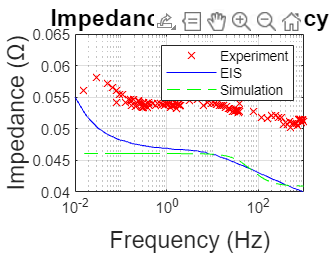

T_S_1 = 8e-04;%main scale = 20s
F_S_1=1/T_S_1;

%FFT for cell voltage & current when f_clk=1Hz
FFT_v_1 = fft(voltage_V_1, L_PRBS);
FFT_i_1 = fft(current_I_1, L_PRBS);

% Initialize arrays to store results
Freq_1 = zeros(1, 25);
MAG_Z_1 = zeros(1, 25);
Phase_Z_1 = zeros(1, 25);
Real_bat_1 = zeros(1, 25);
Imag_bat_1 = zeros(1, 25);

% Loop to cover range of 0.016Hz-0.4Hz 
k_values_1 = 1:25;
for idx = 1:length(k_values_1)
    k_1 = k_values_1(idx);
    N_k_1 = round(F_b_1 * k_1 * L_PRBS / F_S_1 + 1);
    Freq_1(idx) = (N_k_1 - 1) * F_S_1 / L_PRBS;

    V_k_1 = FFT_v_1(N_k_1);
    I_k_1 = FFT_i_1(N_k_1);

    Z_k_1 = V_k_1 / I_k_1;
    MAG_Z_1(idx) = abs(Z_k_1);
    Phase_Z_1(idx) = angle(Z_k_1)*180/pi;
    Real_bat_1(idx) = real(Z_k_1);
    Imag_bat_1(idx) = imag(Z_k_1);
end

% experiment data
Real_bat = [Real_bat_2500, Real_bat_100, Real_bat_5, Real_bat_1];
Imag_bat = [Imag_bat_2500, Imag_bat_100, Imag_bat_5, Imag_bat_1];
MAG_Z = [MAG_Z_1, MAG_Z_5, MAG_Z_100, MAG_Z_2500];
Phase_Z = [Phase_Z_1, Phase_Z_5, Phase_Z_100, Phase_Z_2500];
Freq = [Freq_1, Freq_5, Freq_100, Freq_2500];

%%<<<<<<<<<<<<<<<< plots >>>>>>>>>>>>>>>>>>>>>>>
%impedence vs frequency plot
figure(1);
semilogx(Freq, MAG_Z, 'rx');
hold on;
semilogx(Freq_eis, MAG_Z_eis, 'b-');
hold on;
semilogx(Freq_sim, MAG_Z_sim, 'g--');

title('Impedance vs Frequency');
xlabel("Frequency (Hz)");
ylabel("Impedance (Ω)");
ylim([0.04,0.065]);
xlim([0.01,1000]);
set(gca,'YTick', 0.04:0.005:0.065);
legend('Experiment','EIS','Simulation');
grid on;
hold off;

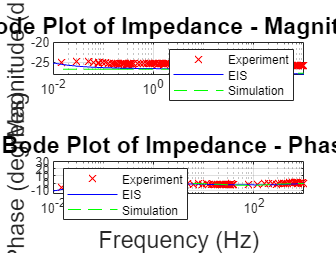


% Bode plot of magnitude and phase
figure(2);
subplot(2,1,1);
semilogx(Freq, 20*log10(MAG_Z), 'rx', 'DisplayName', 'Experiment');
hold on;
semilogx(Freq_eis, 20*log10(MAG_Z_eis), 'b-', 'DisplayName', 'EIS');
hold on;
semilogx(Freq_sim, 20*log10(MAG_Z_sim), 'g--', 'DisplayName', 'Simulation');
hold on;
title('Bode Plot of Impedance - Magnitude');
ylim([-28, -20]);
xlim([0.01,1000]);
% xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
hold off;
legend show;
grid on;
subplot(2,1,2);
semilogx(Freq, Phase_Z, 'rx', 'DisplayName', 'Experiment');
hold on;
semilogx(Freq_eis, Phase_Z_eis, 'b-', 'DisplayName', 'EIS');
hold on;
semilogx(Freq_sim, Phase_Z_sim, 'g--', 'DisplayName', 'Simulation');
hold on;
title('Bode Plot of Impedance - Phase');
ylim([-15, 30]);
xlim([0.01,1000]);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
legend('location', 'northwest');
hold off;
legend show;
grid on;

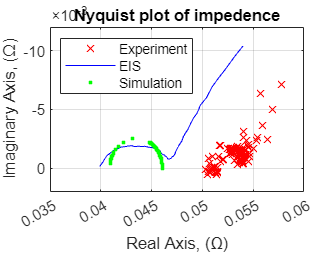


%Nyquist plot 
figure(3);
plot(Real_bat, Imag_bat, 'rx');
hold on;
plot(Real_bat_eis, Imag_bat_eis, 'b-');
hold on;
plot(Real_bat_sim, Imag_bat_sim, 'g.');
title('Nyquist plot of impedence');
xlabel("Real Axis, (Ω)");
ylabel("Imaginary Axis, (Ω)");
xlim([0.035,0.06]);
ylim([-12e-3,2e-3]);
set(gca,'XTick',0.035:0.005:0.06);
set(gca,'ydir','reverse');
legend('Experiment','EIS','Simulation');
legend('location', 'northwest');
grid on;
hold off;